# Subcortical Data Analysis

Below we will show you how to load the data aquired from Thalamus into matlab and generate Figure 5.

## Loading Variables

Contains information for the trial start and end times after excluding outlier trials. Obtained from the HDF5 file under the /events/data and /events/recieved

load('/vol/bd1/Precision_Data/240223_old/001/rec001.Precision2.FiltEvents.mat')

Contains information for the trial start and end times as well as the time axis for the kinematics and subcortical data aquired directly from the HDF5 file.  Kinematic time can be found under /xsens/handengine/recieved. Subcortical data time can be found under /analog/alphaomega/LFP 01/recieved

load('/vol/bd1/Precision_Data/240223_old/001/rec001.Precision2.Events.mat')

Position values obtained from the HDF5 file under /xsens/handengine/data

load('/vol/bd1/Precision_Data/240223_old/001/rec001.Precision2.Position.mat')

Contains the velocity averaged across all the hand (h) and body (b) sensors which was computed from the raw position values. bs and hs contain the speed (computed as Euclidean norm) accross x, y, and z directions

load('/vol/bd1/Precision_Data/240223_old/001/rec001.Precision2.Velocity.mat')

Voltage STN data for 6 channels obtained from the HDF5 file under /analog/alphaomega/LFP ch#/data

load('/vol/bd1/Precision_Data/240223_old/001/rec001.Precision2.AlphaOmegaData.mat')

Voltage STN data after Notch filtering 60Hz

load('/vol/bd1/Precision_Data/240223_old/001/rec001.Precision2.AlphaOmegaNotch.mat')

Contains the STN data for 6 channels after computing power using Multitaper method and meaning over all freq in beta (13-35Hz)

load('/vol/bd1/Precision_Data/240223_old/001/rec001.Precision2.AlphaOmegaBeta.mat')

Time axis for STN data following the Multitaper method

load('/vol/bd1/Precision_Data/240223_old/001/rec001.Precision2.AlphaOmegaPSDtime.mat')

## Voltage Over Trial 10 in The STN

[AlphaOmegaLFP_EventPotentials,time,~]= EventRelatedPotentials(Events.alphaOmegaLfpTime,AlphaOmega.LFP,FiltEvents.movementBounds(:,1),[-2,2]);

Sampling rate: 1374.9971


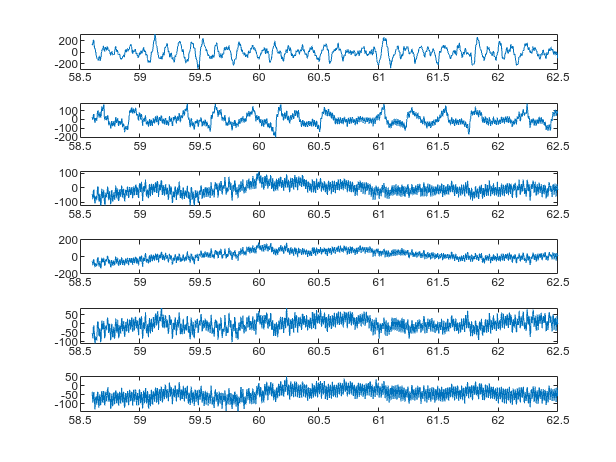

m=squeeze(AlphaOmegaLFP_EventPotentials(10,:,:));

fig = figure('Color', 'white');
tiledlayout(6, 1);
for i = 1:6
    nexttile;
    plot(sq(time(10,:)), m(i,:));
    xlim([58.5,62.5])
end

## Computing Beta Power Over Trial 10

[AlphaOmegaLFP_EventPotentialsBeta,time,~]= EventRelatedPotentials(PSDtime,AlphaOmegaBeta,FiltEvents.movementBounds(:,1),[-2,2]);

Sampling rate: 4.9972


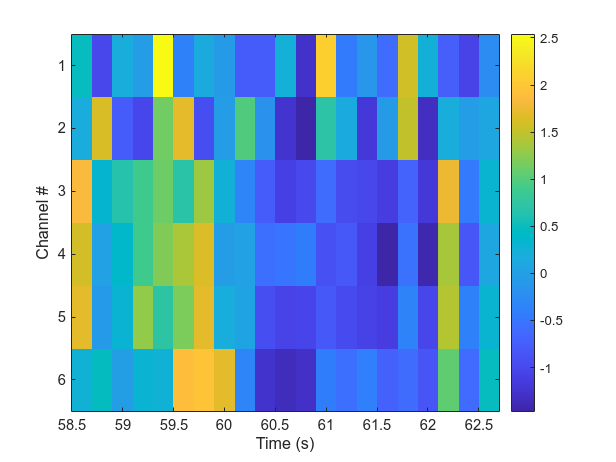

m=sq(AlphaOmegaLFP_EventPotentialsBeta(10,:,:));
mz=zscore(m,0,2);

figure('Color','w')
imagesc(sq(time(10,:)),[],mz)
xlabel('Time (s)')
ylabel('Channel #')
colorbar;

## Computing Velocity of The Hand Over Trial 10

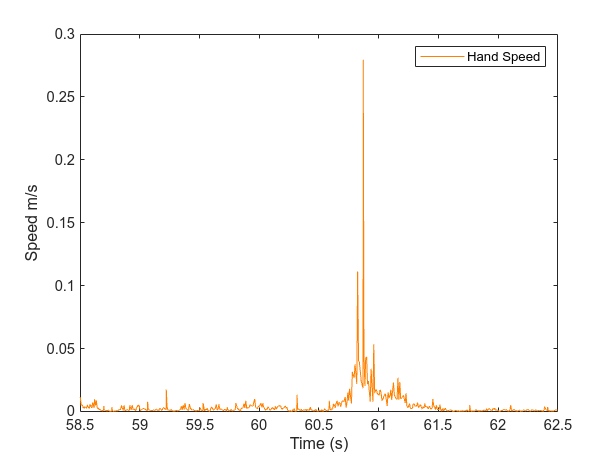

figure('Color','w');
plot(Events.kinematicTimesHand(2:end), V.hs,'Color', [1, 0.5, 0]);
hold on
xlim([58.5,62.5])
xlabel('Time (s)')
ylabel('Speed m/s')
legend({'Hand Speed'})
hold off

## Computing Power Spectra for All Movements Versus Baseline

[PSD, F, timeAxis] = ComputePSD(AlphaOmegaNotch.LFP, Events.alphaOmegaLfpTime, 1375, 0.2, 6.25); 

averagedPSDMovement = averagePSDAcrossIntervals(PSD, Events.movementBounds, timeAxis);

#### Loading Data for Baseline and Computing Power

load('/vol/bd1/Precision_Data/240223_old/002/rec002.Precision2.Events.mat') % STN time axis for baseline
load('/vol/bd1/Precision_Data/240223_old/002/rec002.Precision2.AlphaOmegaNotch.mat') % STN data Notch filtered for baseline
[PSD_Baseline, ~, ~] = ComputePSD(AlphaOmegaNotch.LFP, Events.alphaOmegaLfpTime, 1375, 0.2, 6.25);

averagedPSDBaseline = mean(PSD_Baseline,3);

#### Plotting

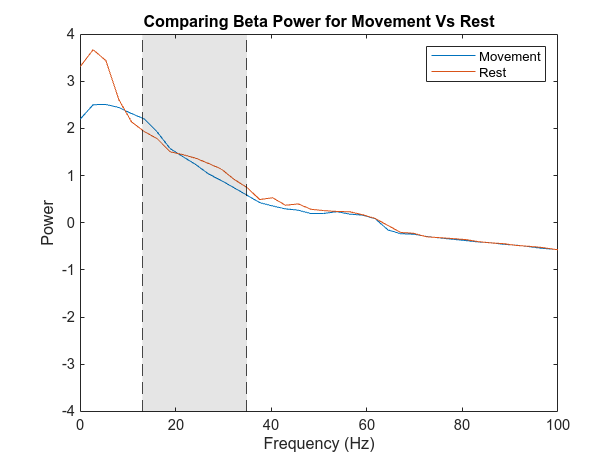

figure('Color', 'white');
plot(F, log10(squeeze(mean(averagedPSDMovement(1:5,:),1))));
hold on;
plot(F, log10(squeeze(mean(averagedPSDBaseline,1))));

start = 13;
stop = 34.91;
xline(start, '--k');
xline(stop, '--k'); 

x = [start stop stop start]; 
y = ylim; 
fill(x, [y(1) y(1) y(2) y(2)], 'k', 'FaceAlpha', 0.1, 'EdgeColor', 'none');

xlabel('Frequency (Hz)');
ylabel('Power');
xlim([0,100])
title('Comparing Beta Power for Movement Vs Rest');
legend('Movement', 'Rest');
hold off;